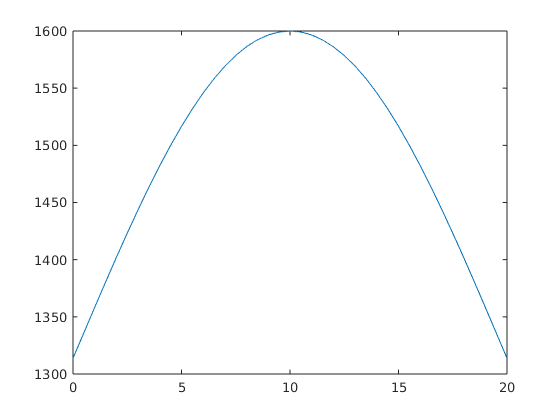

basePath = "~/Dropbox/xps/eQ/build/";

% LOAD FILE
% [file path] = uigetfile('~/Dropbox/xps/eQ/build/*.json', 'Open File');
[file path] = uigetfile(sprintf("%s*.txt", basePath), 'Open File');

thisData = import_eQ_xSliceData(fullfile(path, file), "y", [1, Inf]);
plot(thisData(:, 2), thisData(:,1));

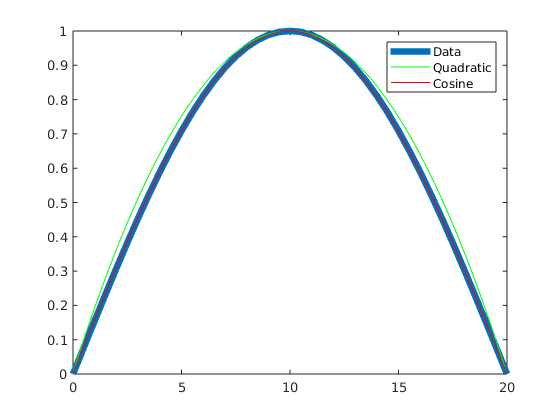


xd = thisData(:,2);
hdata = thisData(:,1);
endValue = hdata(end);

hd = hdata-endValue;
hdmax = max(hd);
hdn = hd/hdmax;

figure;
% PLOT THE ORIGINAL DATA (NORMALIZED TO 0,1)
plot(xd,hdn, 'LineWidth', 5);
hold on;

xfit=linspace(-1,1, length(xd));
hquad=1-xfit.*xfit;
hcos=cos(pi/2 * xfit);

plot(xd, hquad, 'g-');
plot(xd, hcos, 'r-');
hold off;
legend("Data", "Quadratic", "Cosine");

return;


% SAVE THE SLICE DATA ITERATIVELY HERE (INCREMENT INDEX)
i=2;
zs(i).name = "50x500um";
zs(i).xd=xd;
zs(i).hd=hd;
save('~/Dropbox/xps/eQ/matlab/sendRecvData/srData.mat', 'zs')


load Dropbox/xps/eQ/matlab/sendRecvData/srData.mat
h1=zs(1).hd/zs(1).hd(1);
h2=zs(2).hd/zs(2).hd(1);
plot(zs(1).xd, [h1 h2]);
legend(zs.name);

